## Naïve Bayes Code Tests

clear
clc
clf
close all
% loads the letter dataset into letterDatasetNormalised and
% letterDatasetNotNormalised
load letterDatasetClass.mat
letterDataset = letterDatasetNotNormalised;
[X, Y] = letterDataset.extractXYFromTable(letterDataset.trainTable);
X = table2array(X);
Y = table2array(Y);

### Analysis from a Naïve Bayes perspective

% get a default class
nBayes = NBayesClass.getDefaultInstance(letterDataset);

Training loss: 0.35 Test loss: 0.37


nBayes.nBayesModel.Prior

ans =     0.0391    0.0381    0.0381    0.0399    0.0384    0.0378    0.0393    0.0361    0.0379    0.0361    0.0367    0.0384    0.0396    0.0383    0.0382    0.0407    0.0386    0.0375    0.0381    0.0413    0.0404    0.0393    0.0377    0.0387    0.0394    0.0366


[dfltLTrainLoss, dfltTestLoss] = nBayes.getModelLoss();
nBayes.setPriorDistributionEmpirical();
nBayes.nBayesModel.Prior

ans =     0.0413    0.0379    0.0399    0.0383    0.0393    0.0391    0.0396    0.0387    0.0382    0.0375    0.0381    0.0361    0.0381    0.0361    0.0384    0.0381    0.0384    0.0394    0.0386    0.0407    0.0393    0.0377    0.0404    0.0378    0.0366    0.0368


[empTrainLoss, emptTestLoss] = nBayes.getModelLoss();
fprintf("Default Training Loss:   %0.02f Test Loss %0.02f\n", dfltLTrainLoss, dfltTestLoss);

Default Training Loss:   0.35 Test Loss 0.37


fprintf("Empirical Training Loss: %0.02f Test Loss %0.02f\n", empTrainLoss, emptTestLoss);

Empirical Training Loss: 0.35 Test Loss 0.37


model = nBayes.nBayesModel

model =   ClassificationNaiveBayes
            PredictorNames: {'xBox'  'yBox'  'width'  'height'  'onPixelCount'  'xBar'  'yBar'  'x2Bar'  'y2Bar'  'xyBar'  'x2yBr'  'xy2Br'  'xEge'  'xEgvy'  'yEge'  'yEgvx'}
              ResponseName: 'TargetAscii'
     CategoricalPredictors: []
                ClassNames: [A    B    C    D    E    F    G    H    I    J    K    L    M    N    O    P    Q    R    S    T    U    V    W    X    Y    Z]
            ScoreTransform: 'none'
           NumObservations: 16000
         DistributionNames: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {26×16 cell}


  Properties, Methods


Set prior distribution to an empirical distribution

model = nBayes.setPriorDistributionEmpirical()

model =   ClassificationNaiveBayes
            PredictorNames: {'xBox'  'yBox'  'width'  'height'  'onPixelCount'  'xBar'  'yBar'  'x2Bar'  'y2Bar'  'xyBar'  'x2yBr'  'xy2Br'  'xEge'  'xEgvy'  'yEge'  'yEgvx'}
              ResponseName: 'TargetAscii'
     CategoricalPredictors: []
                ClassNames: [A    B    C    D    E    F    G    H    I    J    K    L    M    N    O    P    Q    R    S    T    U    V    W    X    Y    Z]
            ScoreTransform: 'none'
           NumObservations: 16000
         DistributionNames: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
    DistributionParameters: {26×16 cell}


  Properties, Methods


cvModel = crossval(model);
modelLoss = kfoldLoss(cvModel);
crossValModel = crossval(model);
fprintf("KFold Loss:: %0.02f\n", kfoldLoss(crossValModel));

KFold Loss:: 0.36


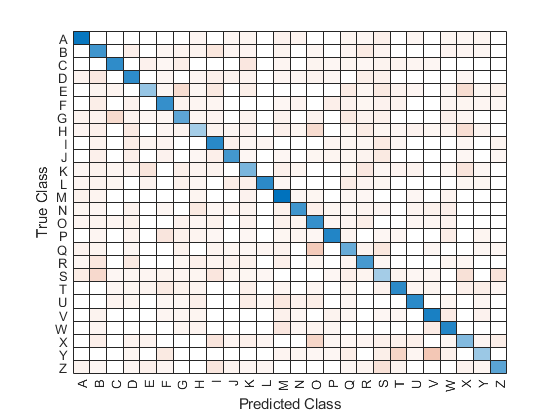

[predicted, score] = resubPredict(model);
confusionMat = confusionchart(categorical(Y), predicted);

Look at the classifiers that have been setup for each attribute. There are 16 of them, each one configurable.

disp(model.DistributionNames(:,:));

  Columns 1 through 8

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}

  Columns 9 through 16

    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}    {'normal'}



[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.02f Test loss: %0.02f\n", trainingLoss, testLoss);

ans = 0.3549

### Try Kernel Distribution

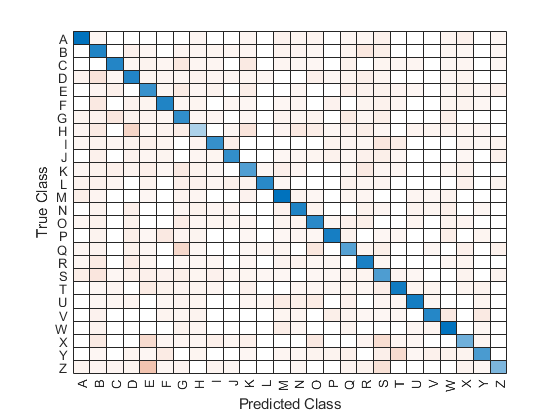

% get a kernel class
nBayes = NBayesClass.getKernelInstance(letterDataset);
model = nBayes.setPriorDistributionEmpirical();
predictions = resubPredict(model);
confusionMat = confusionchart(categorical(Y), predictions);

[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.02f Test loss: %0.02f\n", trainingLoss, testLoss);

Training loss: 0.30 Test loss: 0.32


### Try Optimization

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33644 |      69.246 |     0.33644 |     0.33644 |       kernel |        1.287 |


|    2 | Accept |     0.35725 |     0.52633 |     0.33644 |     0.34644 |       normal |            - |


|    3 | Accept |     0.35725 |     0.45133 |     0.33644 |     0.33644 |       normal |            - |


|    4 | Accept |     0.51019 |      69.941 |     0.33644 |     0.33644 |       kernel |       8.6162 |


|    5 | Best   |     0.25006 |      42.969 |     0.25006 |     0.25007 |       kernel |      0.30805 |


|    6 | Best   |     0.24919 |      42.651 |     0.24919 |     0.24914 |       kernel |      0.25009 |


|    7 | Accept |     0.24919 |      42.549 |     0.24919 |     0.24916 |       kernel |      0.25013 |


|    8 | Accept |     0.24919 |      42.723 |     0.24919 |     0.24917 |       kernel |      0.25022 |


|    9 | Accept |     0.24919 |      42.481 |     0.24919 |     0.24917 |       kernel |      0.26337 |


|   10 | Accept |     0.24919 |      42.516 |     0.24919 |     0.24917 |       kernel |      0.25043 |


|   11 | Accept |     0.27044 |       54.77 |     0.24919 |     0.24922 |       kernel |      0.61428 |


|   12 | Accept |     0.61375 |      71.262 |     0.24919 |      0.2492 |       kernel |       14.998 |


|   13 | Accept |     0.24938 |      41.959 |     0.24919 |     0.24924 |       kernel |      0.27578 |


|   14 | Accept |     0.44525 |      74.045 |     0.24919 |     0.24919 |       kernel |       3.1633 |


|   15 | Accept |     0.24931 |      41.731 |     0.24919 |      0.2492 |       kernel |      0.26992 |


|   16 | Accept |     0.25769 |      41.854 |     0.24919 |     0.24921 |       kernel |      0.44953 |


|   17 | Accept |     0.29875 |      61.511 |     0.24919 |     0.24921 |       kernel |      0.87686 |


|   18 | Accept |     0.48094 |       70.42 |     0.24919 |     0.24921 |       kernel |       5.1232 |


|   19 | Accept |      0.2525 |      41.711 |     0.24919 |     0.24921 |       kernel |      0.37089 |


|   20 | Accept |     0.39281 |       72.77 |     0.24919 |     0.24921 |       kernel |       1.9431 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25031 |      42.615 |     0.24919 |     0.24919 |       kernel |      0.33501 |


|   22 | Accept |     0.26306 |       54.24 |     0.24919 |     0.24919 |       kernel |      0.52137 |


|   23 | Best   |     0.24913 |      42.656 |     0.24913 |     0.24918 |       kernel |      0.25916 |


|   24 | Accept |     0.24944 |      41.683 |     0.24913 |     0.24918 |       kernel |      0.28773 |


|   25 | Accept |     0.24913 |       42.02 |     0.24913 |     0.24918 |       kernel |      0.25891 |


|   26 | Accept |     0.24913 |      41.881 |     0.24913 |     0.24917 |       kernel |       0.2586 |


|   27 | Accept |     0.54869 |      71.311 |     0.24913 |     0.24917 |       kernel |       11.674 |


|   28 | Accept |     0.28331 |      53.069 |     0.24913 |     0.24917 |       kernel |      0.72876 |


|   29 | Accept |       0.423 |      73.045 |     0.24913 |     0.24917 |       kernel |       2.4778 |


|   30 | Accept |      0.4925 |      72.554 |     0.24913 |     0.24917 |       kernel |       6.5632 |


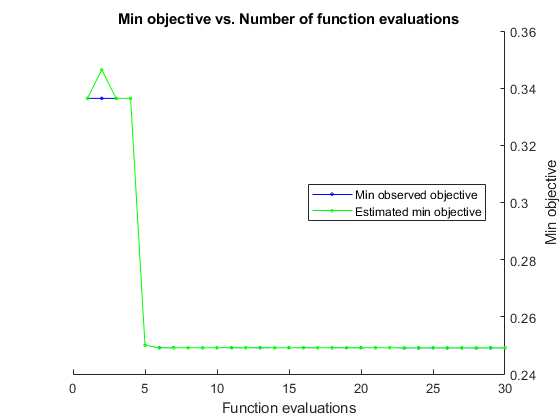

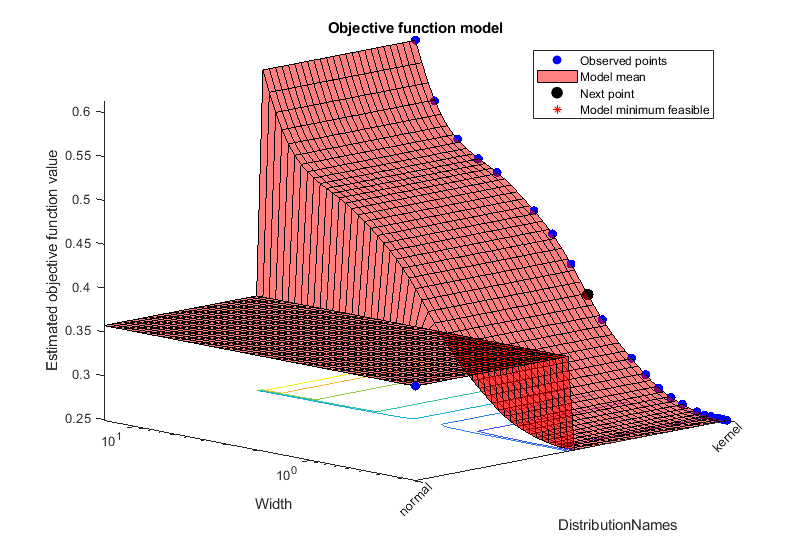


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1542.891 seconds
Total objective function evaluation time: 1503.1615

Best observed feasible point:
    DistributionNames     Width 
    _________________    _______

         kernel          0.25916

Observed objective function value = 0.24913
Estimated objective function value = 0.24917
Function evaluation time = 42.6558

Best estimated feasible point (according to models):
    DistributionNames     Width 
    _________________    _______

         kernel          0.25916

Estimated objective function value = 0.24917
Estimated function evaluation time = 42.0215



obj =   NBayesClass with properties:

          randomSeed: 300
               debug: 1
             dataset: [1×1 LetterDatasetClass]
         nBayesModel: [1×1 ClassificationNaiveBayes]
                   x: [16000×16 table]
                   y: [16000×1 table]
                  xt: [4000×16 table]
                  yt: [4000×1 table]
    distNamesDefault: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
     distNamesKernel: {'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'}


% perform on not normalised dataset
nBayes = NBayesClass(letterDataset);
nBayes.fitMatlabHyperparameterOptimization();

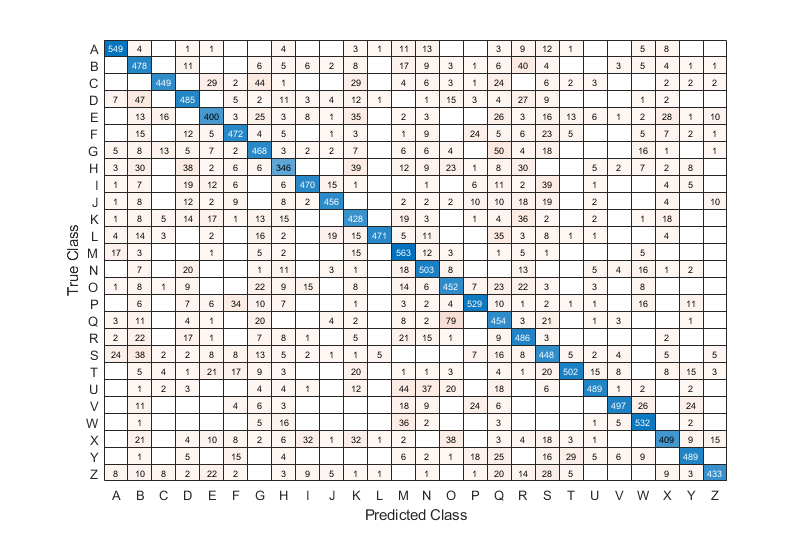

predictions = resubPredict(nBayes.nBayesModel);
confusionMat = confusionchart(categorical(Y), predictions);

[trainingLoss, testLoss] = nBayes.getModelLoss();
fprintf("Training loss: %0.02f Test loss: %0.02f\n", trainingLoss, testLoss);

Training loss: 0.23 Test loss: 0.25


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|    1 | Best   |     0.33644 |      70.916 |     0.33644 |     0.33644 |       kernel |       0.0858 |


|    2 | Accept |     0.35725 |     0.42445 |     0.33644 |     0.34644 |       normal |            - |


|    3 | Accept |     0.35725 |      0.4038 |     0.33644 |     0.33644 |       normal |            - |


|    4 | Accept |     0.51019 |      68.508 |     0.33644 |     0.33644 |       kernel |      0.57441 |


|    5 | Best   |     0.25006 |      43.664 |     0.25006 |     0.25007 |       kernel |     0.020537 |


|    6 | Best   |     0.24919 |        42.9 |     0.24919 |     0.24914 |       kernel |     0.016673 |


|    7 | Accept |     0.24919 |      42.451 |     0.24919 |     0.24916 |       kernel |     0.016675 |


|    8 | Accept |     0.24919 |      42.617 |     0.24919 |     0.24917 |       kernel |     0.016682 |


|    9 | Accept |     0.24919 |      42.362 |     0.24919 |     0.24917 |       kernel |     0.017558 |


|   10 | Best   |     0.24913 |      43.339 |     0.24913 |     0.24916 |       kernel |     0.016708 |


|   11 | Accept |     0.27044 |      53.959 |     0.24913 |     0.24922 |       kernel |     0.040952 |


|   12 | Accept |     0.61375 |      71.505 |     0.24913 |     0.24918 |       kernel |      0.99985 |


|   13 | Accept |     0.24938 |      43.268 |     0.24913 |     0.24923 |       kernel |     0.018363 |


|   14 | Accept |     0.44525 |      73.196 |     0.24913 |     0.24918 |       kernel |      0.21089 |


|   15 | Accept |     0.24931 |      42.268 |     0.24913 |      0.2492 |       kernel |     0.017963 |


|   16 | Accept |     0.25769 |      42.308 |     0.24913 |      0.2492 |       kernel |     0.029968 |


|   17 | Accept |     0.29875 |      62.152 |     0.24913 |      0.2492 |       kernel |     0.058457 |


|   18 | Accept |     0.48094 |      72.751 |     0.24913 |      0.2492 |       kernel |      0.34155 |


|   19 | Accept |      0.2525 |      42.011 |     0.24913 |      0.2492 |       kernel |     0.024723 |


|   20 | Accept |     0.39281 |      75.637 |     0.24913 |      0.2492 |       kernel |      0.12954 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | Distribution-|        Width |
|      | result |             | runtime     | (observed)  | (estim.)    | Names        |              |
|=====================================================================================================|
|   21 | Accept |     0.25031 |      41.653 |     0.24913 |     0.24919 |       kernel |     0.022334 |


|   22 | Accept |     0.26306 |      54.165 |     0.24913 |     0.24919 |       kernel |     0.034758 |


|   23 | Accept |     0.24913 |      41.873 |     0.24913 |     0.24918 |       kernel |     0.017277 |


|   24 | Accept |     0.24944 |      41.768 |     0.24913 |     0.24918 |       kernel |     0.019182 |


|   25 | Accept |     0.24913 |       41.83 |     0.24913 |     0.24917 |       kernel |     0.017261 |


|   26 | Accept |     0.24913 |      41.839 |     0.24913 |     0.24917 |       kernel |     0.017202 |


|   27 | Accept |     0.54869 |      69.937 |     0.24913 |     0.24917 |       kernel |       0.7783 |


|   28 | Accept |     0.28331 |      53.648 |     0.24913 |     0.24917 |       kernel |     0.048584 |


|   29 | Accept |       0.423 |      72.557 |     0.24913 |     0.24917 |       kernel |      0.16519 |


|   30 | Accept |      0.4925 |      70.956 |     0.24913 |     0.24917 |       kernel |      0.43754 |


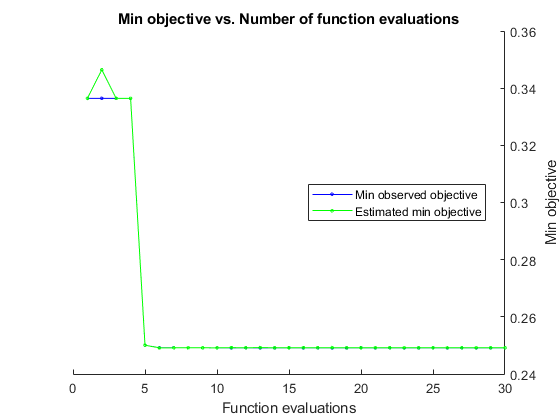

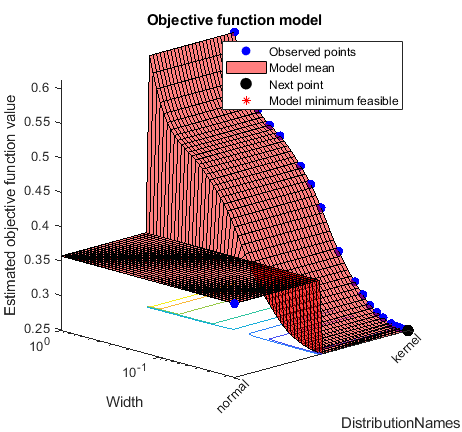


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 1530.2247 seconds
Total objective function evaluation time: 1506.8655

Best observed feasible point:
    DistributionNames     Width  
    _________________    ________

         kernel          0.016708

Observed objective function value = 0.24913
Estimated objective function value = 0.24919
Function evaluation time = 43.3392

Best estimated feasible point (according to models):
    DistributionNames     Width  
    _________________    ________

         kernel          0.017277

Estimated objective function value = 0.24917
Estimated function evaluation time = 42.2567



obj =   NBayesClass with properties:

          randomSeed: 300
               debug: 1
             dataset: [1×1 LetterDatasetClass]
         nBayesModel: [1×1 ClassificationNaiveBayes]
                   x: [16000×16 table]
                   y: [16000×1 table]
                  xt: [4000×16 table]
                  yt: [4000×1 table]
    distNamesDefault: {'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'  'normal'}
     distNamesKernel: {'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'  'kernel'}



% perform on normalised dataset
letterDataset = letterDatasetNormalised;
nBayesNorm = NBayesClass(letterDataset);
nBayesNorm.fitMatlabHyperparameterOptimization();

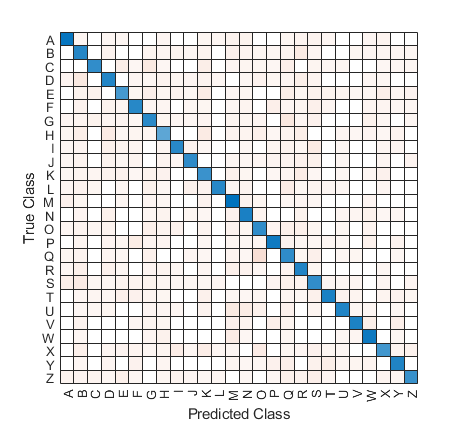

predictions = resubPredict(nBayesNorm.nBayesModel);
confusionMat = confusionchart(categorical(Y), predictions);

[trainingLoss, testLoss] = nBayesNorm.getModelLoss();
fprintf("Training loss: %0.02f Test loss: %0.02f\n", trainingLoss, testLoss);

Training loss: 0.23 Test loss: 0.25
